# 2. Finding Natural Patterns in Data

## Dimensionality Reduction

When the dimension is large, it is difficult to visualize the data to look for patterns or groups. You can try to visualize the data by transforming it into a 2 or 3 dimenstional coordinate space.

load('bbstats.mat')

### 1. Multidimensional scaling

% open("2_1 Multidimensional Scaling.pdf") % Read this file before start
d= pdist(statsnorm)

d =     6.7062    2.5556    8.4428    2.0170   10.1507    1.7311    3.8159    3.9804    5.4840    7.3683    4.6727    3.1389    2.6189    3.7909    1.0975   10.0537    3.7521    1.9145    7.2446    1.9272    2.4475    1.6802    3.5490    1.5395    6.2925    2.4845    7.6419    7.3971    3.8171    5.5304    3.0083    4.5623    1.4234   11.2734    5.6239    2.9499    2.3175   11.6451    4.6829    5.0989    4.1412    6.5963    1.3655    3.6308    7.8043    2.2116    2.1020    2.8436    2.8645    6.5978


[X,e] = cmdscale(d)

X =    -2.5485    1.2178   -0.0925   -0.7242   -0.4860   -0.0325    0.0950   -0.2356   -0.2837   -0.0311    0.2154   -0.3464    0.2172    0.0978   -0.0238   -0.0171   -0.0054
    2.1322   -3.1352    0.3102   -0.3670    0.3826    0.3179   -1.2126   -0.9061   -1.0428    0.1654    0.3707   -0.0027    0.2806   -0.0609   -0.0598    0.0183   -0.0009
   -0.5333    0.3654    0.7177   -0.3299   -0.3373    0.2117   -0.1612    0.2554   -0.3007    0.3865   -0.0195   -0.2278   -0.2815   -0.1042   -0.0117    0.0792    0.0072
    5.6463    2.3930    0.8472   -1.4487   -0.0339    0.2938   -0.2370    0.1329    0.2902   -0.3182   -0.1195   -0.1888   -0.2257    0.0342   -0.1956    0.0093    0.0063
   -2.6830    1.7338    0.0975    0.5254   -0.6947    0.3721   -0.4348    0.1247    0.3378   -0.8879    0.1100    0.3024    0.1182    0.0186   -0.0138   -0.0294   -0.0056
    5.5690   -4.4839    0.8503    0.2245    0.0946   -0.3723    0.5065    0.2828    0.8058    0.0967    0.2446    0.3213    0.3334   -0.4159 

e = 	1.0e+03 *

    9.4009
    5.1765
    1.2410
    0.7806
    0.4912
    0.4028
    0.3401
    0.2905
    0.2732
    0.1683


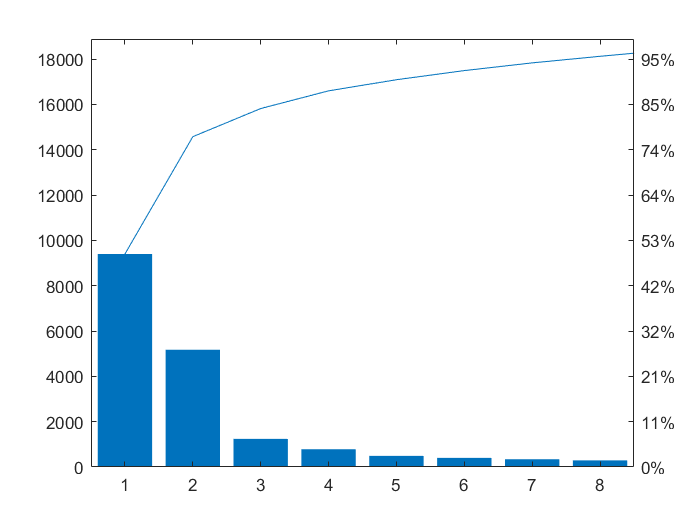

pareto(e)

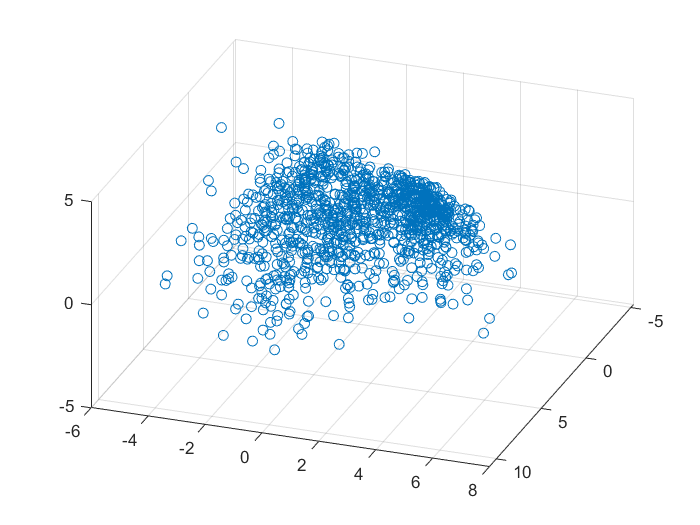

figure
scatter3(X(:,1),X(:,2),X(:,3))
view(110,40)

### 2. Principal Component Analysis

% open("2_2 Principal Component Analysis.pdf") % Read this file before start
[pcs,scrs,~,~,pexp] = pca(statsnorm)

pcs =    -0.0437    0.3955    0.3115    0.0918   -0.0149   -0.1874   -0.2443    0.1325    0.3497    0.6914    0.1448   -0.0396    0.0033   -0.0037    0.0285   -0.0017   -0.0008
   -0.0400    0.3831    0.2786    0.1518   -0.4145   -0.2100   -0.4238   -0.0256    0.0359   -0.5788   -0.0979   -0.0668    0.0620    0.0170   -0.0211    0.0028    0.0005
    0.3266    0.0065    0.0355   -0.1691   -0.0018    0.0860    0.0323   -0.2343    0.1017    0.0899   -0.3122   -0.3878    0.7256   -0.0758    0.0255    0.0283    0.0110
    0.3339   -0.0080    0.0895    0.1877    0.0352    0.0885    0.1012   -0.0254    0.1896   -0.0920    0.0995   -0.0602   -0.1914   -0.3528   -0.0501    0.1608    0.7602
    0.1234    0.3747   -0.0763   -0.2075   -0.0429    0.5652   -0.1010    0.0311   -0.2442   -0.0415    0.6038   -0.1289    0.0862    0.0912   -0.0671    0.0017   -0.0135
    0.2211    0.2986    0.0536   -0.1822    0.0992    0.2671   -0.2173   -0.3435   -0.2658    0.1699   -0.5307    0.2805   -0.3444   -0.025

scrs =    -2.5485    1.2178    0.0925    0.7242   -0.4860   -0.0325   -0.0950   -0.2356    0.2837    0.0311    0.2154    0.3464   -0.2172   -0.0978   -0.0238    0.0171   -0.0054
    2.1322   -3.1352   -0.3102    0.3670    0.3826    0.3179    1.2126   -0.9061    1.0428   -0.1654    0.3707    0.0027   -0.2806    0.0609   -0.0598   -0.0183   -0.0009
   -0.5333    0.3654   -0.7177    0.3299   -0.3373    0.2117    0.1612    0.2554    0.3007   -0.3865   -0.0195    0.2278    0.2815    0.1042   -0.0117   -0.0792    0.0072
    5.6463    2.3930   -0.8472    1.4487   -0.0339    0.2938    0.2370    0.1329   -0.2902    0.3182   -0.1195    0.1888    0.2257   -0.0342   -0.1956   -0.0093    0.0063
   -2.6830    1.7338   -0.0975   -0.5254   -0.6947    0.3721    0.4348    0.1247   -0.3378    0.8879    0.1100   -0.3024   -0.1182   -0.0186   -0.0138    0.0294   -0.0056
    5.5690   -4.4839   -0.8503   -0.2245    0.0946   -0.3723   -0.5065    0.2828   -0.8058   -0.0967    0.2446   -0.3213   -0.3334    0.41

pexp =    49.7745
   27.4075
    6.5706
    4.1332
    2.6006
    2.1326
    1.8005
    1.5383
    1.4464
    0.8912


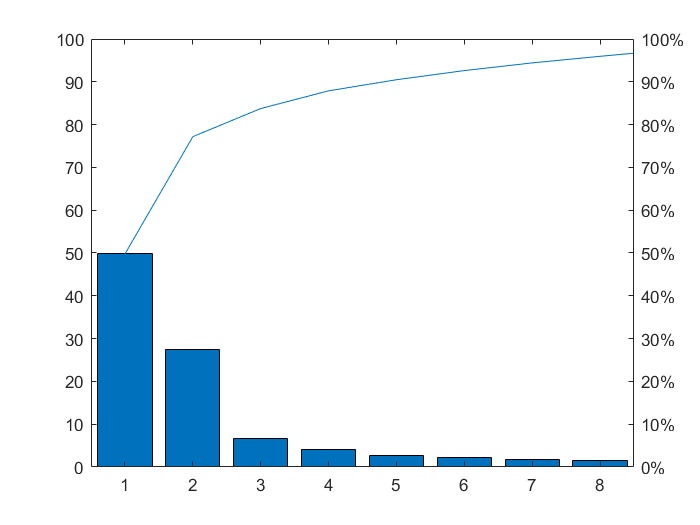

pareto(pexp)

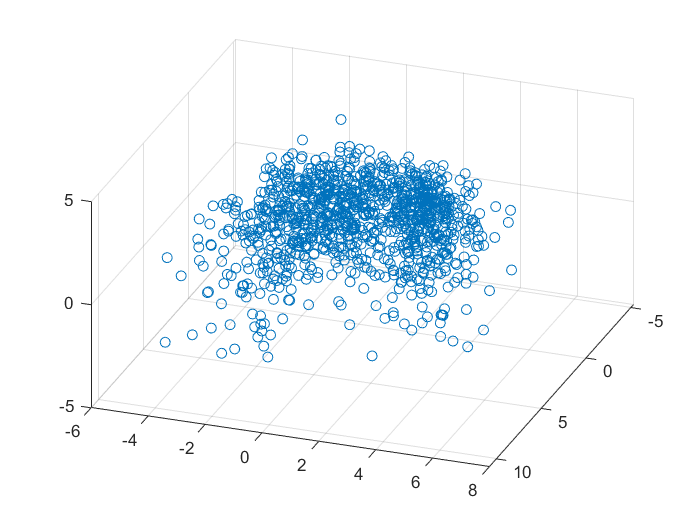

figure
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)

## Unsupervised Learning

### 1. k-Means Clustering(1/3)

% open("2_3 k-Means Clustering.pdf") % Read this file before start
g = kmeans(statsnorm,2)

g =      1
     2
     1
     2
     1
     2
     1
     1
     2
     1


[g,c] = kmeans(statsnorm,2,"Replicates",5)

g =      1
     2
     1
     2
     1
     2
     1
     1
     2
     1


c =     0.0535    0.0594   -0.5327   -0.5384   -0.1939   -0.3571   -0.3742   -0.4008   -0.1330   -0.5111   -0.3007   -0.5310   -0.5314   -0.4840   -0.4950   -0.2652   -0.2557
   -0.1170   -0.1298    1.1647    1.1771    0.4239    0.7808    0.8182    0.8762    0.2907    1.1174    0.6574    1.1608    1.1618    1.0581    1.0821    0.5798    0.5590


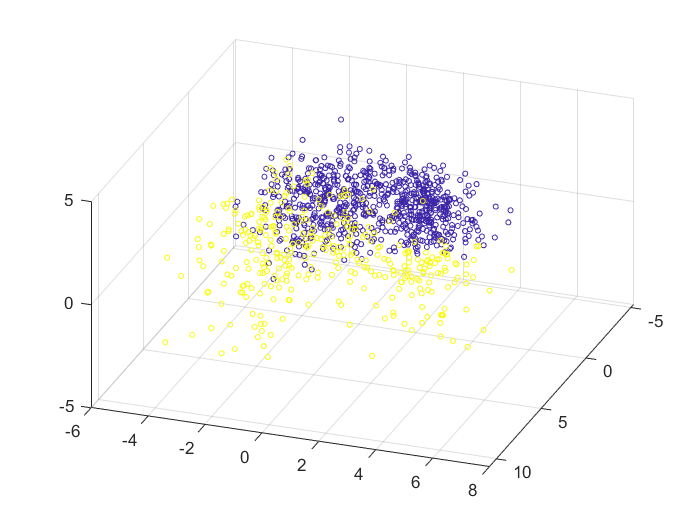

figure
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)
view(110,40)

### 2. Gaussian Mixture Model(2/3)

Grouping by GMM depends on parameter options. Try different 'RegularizationValue', 'CovarianceType' options.

% open("2_4 GMM Clustering.pdf") % Read this file before start
gm = fitgmdist(statsnorm,2,"Replicates",5,"RegularizationValue",0.02,"CovarianceType","diagonal")% Fit GMM to 'statsnorm' Data

gm = 

17개 차원에 2개 성분을 갖는 가우스 혼합 분포




 
% Use 2 instead of 1, because probability results are always helpful
g = cluster(gm,statsnorm)% 1. Cluster statsnorm according to the GMM and Output the grouping results

g =      2
     1
     2
     1
     2
     1
     2
     2
     1
     1


[g,~,p] = cluster(gm,statsnorm) % 2. Cluster statsnorm according to the GMM and Output the grouping and probability results  

g =      2
     1
     2
     1
     2
     1
     2
     2
     1
     1


p =     0.0000    1.0000
    1.0000    0.0000
    0.0001    0.9999
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0005    0.9995
    1.0000    0.0000
    0.9126    0.0874


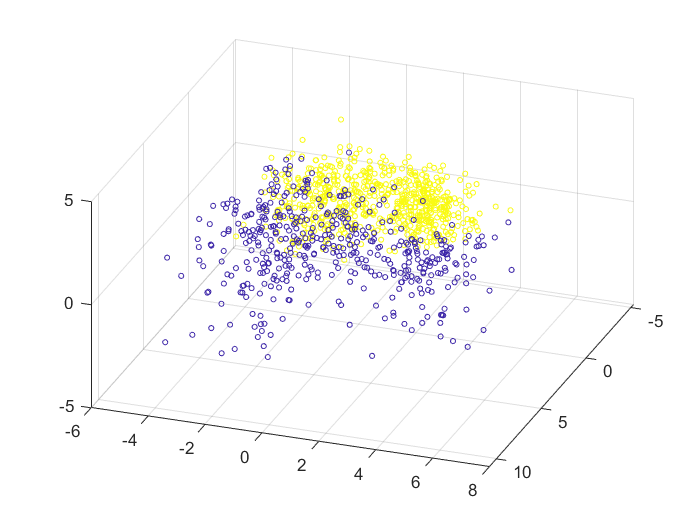


% Visualize groups
figure
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)
view(110,40)

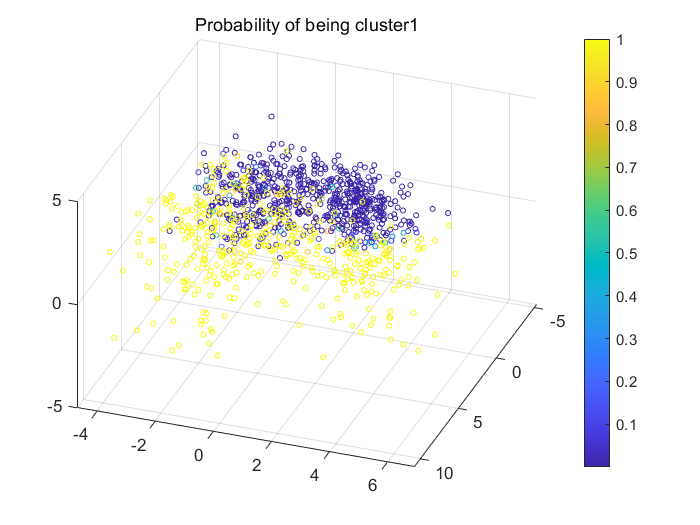

% Visualize probabilities
figure
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,p(:,1))
colorbar
view(110,40)
title("Probability of being cluster1")

### 3. Interpreting the Groups

1. Visualizing observations in cluseters grouped by k-Means

[g, c ] = kmeans(statsnorm,2,"Replicates",5)
%중요 
parallelcoords(statsnorm,"Group",g)%'parallelcoords' function to visualize observation in clussters
xticklabels(labels)% Is it discrete visualization?
parallelcoords(statsnorm,"Group",g,"Quantile",0.25)% Much better now
parallelcoords(c,"Group",1:2)% Use the centroid to visualize

2. Correlation between the groups and player positions (IMPORTANT because you can visualize clustering quality)

% counts = crosstab(yCat,grp)

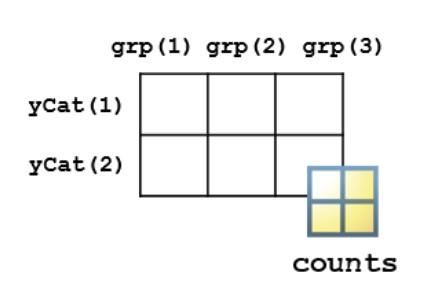

positions = data.pos

positions = 1112×1 categorical 배열
     F-C 
     G 
     G-F 
     F 
     F-C 
     G 
     F-G 
     G 
     F-G 
     G-F 
     F 
     G 
     G 
     C-F 
     G 
     F 
     G 
     G 
     F 
     G 
     C-F 
     F 
     F 
     F-C 
     C 
     G 
     F-C 
     G 
     F-G 
     F-G 


counts1 = crosstab(data.pos,g)

counts1 =    164   203
    51    48
    28    21
   109   207
    49    69
    12    32
    33    86


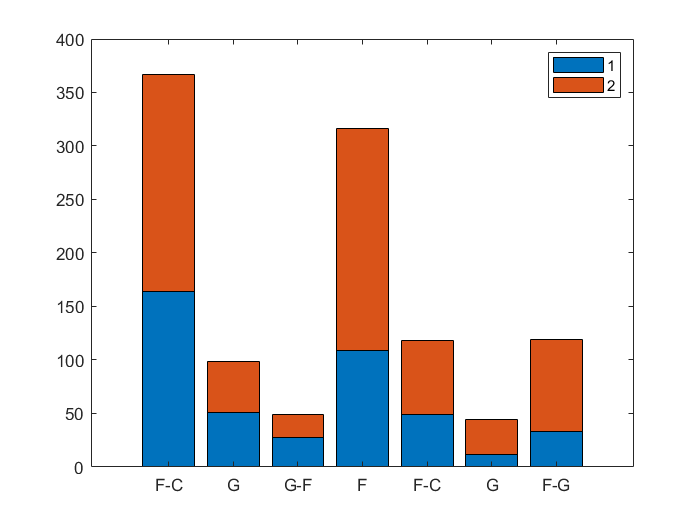


figure
bar(counts1,"stacked")
xticklabels(positions)
legend({'1','2'})


counts2 = crosstab(g,data.pos)

counts2 =    164    51    28   109    49    12    33
   203    48    21   207    69    32    86


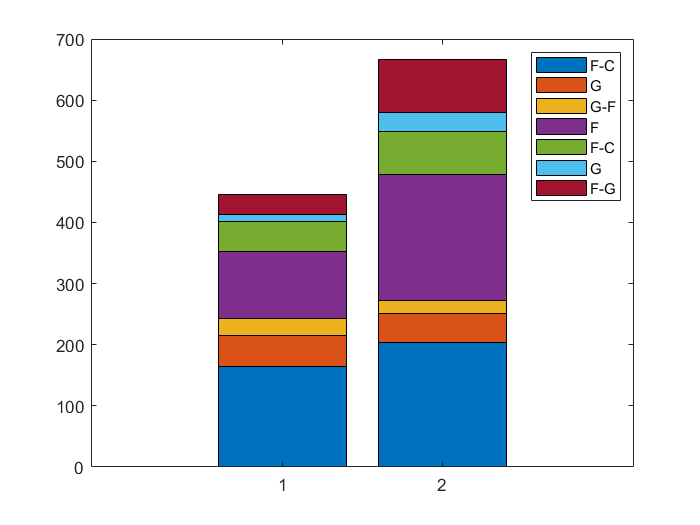

figure
bar(counts2,"stacked")
xticklabels({'1','2'})
legend(positions)

### 4. Evaluating Clustering Quality

% Group data into 2~5 clusters and see their silhouette values.
% Is it easy to find the optimal number of clusters?
[g,c] = kmeans(statsnorm,2,"Replicates",5)

g =      1
     2
     1
     2
     1
     2
     1
     1
     2
     1


c =     0.0542    0.0614   -0.5315   -0.5370   -0.1930   -0.3562   -0.3743   -0.4010   -0.1327   -0.5093   -0.2983   -0.5293   -0.5297   -0.4831   -0.4942   -0.2660   -0.2565
   -0.1189   -0.1348    1.1668    1.1790    0.4238    0.7821    0.8218    0.8805    0.2913    1.1182    0.6549    1.1621    1.1629    1.0606    1.0849    0.5840    0.5631


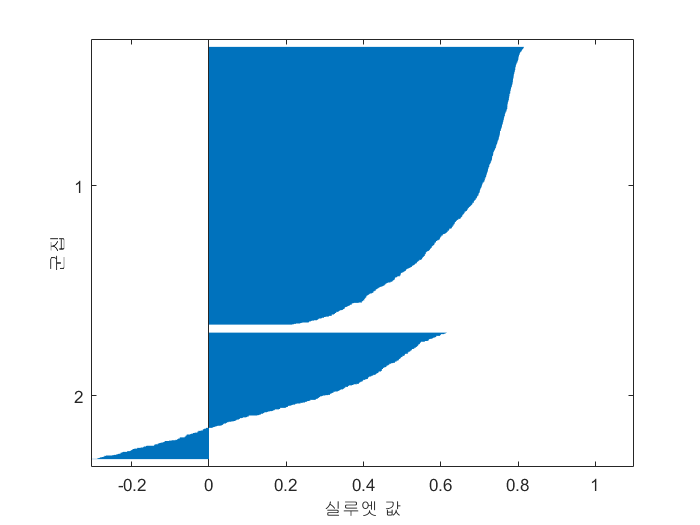

silhouette(statsnorm,g)

[g,c] = kmeans(statsnorm,3,"Replicates",5)

g =      1
     3
     1
     2
     1
     2
     1
     3
     3
     3


c =     0.8009    0.7794   -0.5663   -0.6062    0.4529    0.0740   -0.7201   -0.6648    0.3948   -0.5687    0.1686   -0.6484   -0.5684   -0.3683   -0.4485   -0.7711   -0.7420
   -0.0277   -0.0512    1.3174    1.4117    0.5074    0.9296    0.8828    0.9953    0.3566    1.2999    0.7284    1.3874    1.3955    1.2985    1.3230    0.6234    0.5956
   -0.7536   -0.7181   -0.2840   -0.3049   -0.7554   -0.6564    0.1377    0.0136   -0.6045   -0.2706   -0.6207   -0.2489   -0.3311   -0.4627   -0.4009    0.3500    0.3395


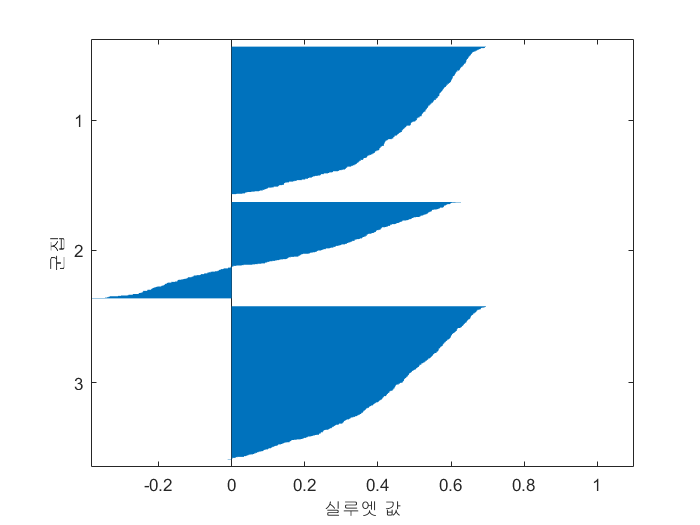

silhouette(statsnorm,g)

[g,c] = kmeans(statsnorm,4,"Replicates",5)

g =      2
     3
     2
     1
     2
     4
     2
     3
     3
     3


c =     0.7761    0.7413    0.7437    0.6155    1.3872    1.3592   -0.2162    0.0976    1.1359    0.5510    1.1617    0.5641    0.7156    0.7629    0.6288   -0.5849   -0.5800
    0.6269    0.5980   -0.8978   -0.8208    0.0075   -0.3560   -0.7555   -0.7701    0.0299   -0.8044   -0.3154   -0.8511   -0.8043   -0.6031   -0.6504   -0.6906   -0.6701
   -0.8507   -0.7939   -0.1403   -0.2086   -0.7548   -0.5986    0.2620    0.1191   -0.5982   -0.1522   -0.5193   -0.1465   -0.2379   -0.4007   -0.3329    0.4543    0.4456
   -0.5541   -0.5709    1.4483    1.5976   -0.1346    0.4006    1.4711    1.4146   -0.2125    1.5146    0.3865    1.5943    1.4916    1.3297    1.4651    1.3679    1.3330


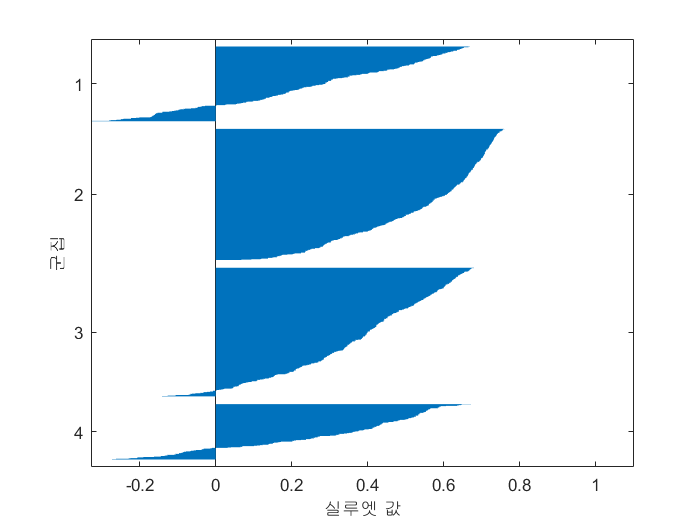

silhouette(statsnorm,g)

[g,c] = kmeans(statsnorm,5,"Replicates",5)

g =      5
     2
     5
     3
     5
     4
     1
     2
     2
     2


c =    -0.1710   -0.2183   -1.0530   -0.8690   -0.6648   -0.8522   -0.4862   -0.6335   -0.5371   -0.8597   -1.0028   -0.8574   -0.8848   -0.7968   -0.7707   -0.2887   -0.2942
   -0.7249   -0.7063    0.2856    0.1594   -0.5687   -0.3538    0.4426    0.4001   -0.5008    0.1615   -0.1706    0.2333    0.1381   -0.1177   -0.0478    0.6667    0.6574
    0.7816    0.7284    1.1490    1.1175    1.5971    1.8478    0.0311    0.3062    1.3002    0.9805    1.2998    1.0250    1.2061    1.3115    1.1791   -0.4953   -0.5016
   -0.6371   -0.6237    1.5826    1.7555   -0.1438    0.4119    1.7198    1.6121   -0.2258    1.7180    0.3802    1.7417    1.6263    1.4952    1.6487    1.4865    1.4529
    0.8576    0.9068   -0.3939   -0.5150    0.6286    0.2471   -0.7028   -0.5828    0.5938   -0.4479    0.4791   -0.5567   -0.4613   -0.2772   -0.3832   -0.8056   -0.7726


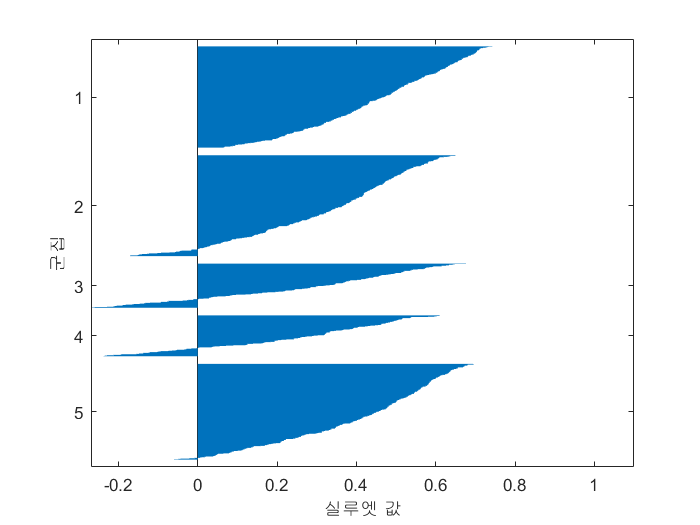

silhouette(statsnorm,g)

% cluster를 몇 개의 그룹으로 나누어야 할지 결정 'evalclusters' function finds you the optimal number of clusters
clustev1 = evalclusters(statsnorm,"kmeans","silhouette","KList",2:5)

clustev1 =   SilhouetteEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [0.5189 0.3821 0.3983 0.3784]
           OptimalK: 2


clustev2 = evalclusters(statsnorm,"kmeans","CalinskiHarabasz","KList",2:5)

clustev2 =   CalinskiHarabaszEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [556.5509 471.0667 455.9517 417.9823]
           OptimalK: 2


clustev3 = evalclusters(statsnorm,"kmeans","DaviesBouldin","KList",2:5)

clustev3 =   DaviesBouldinEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.3083 1.3180 1.2833 1.2865]
           OptimalK: 4


clustev4 = evalclusters(statsnorm,"kmeans","gap","KList",2:5)

clustev4 =   GapEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.4514 1.5536 1.6547 1.7253]
           OptimalK: 5


###  5. Hierarchical Clustering(3/3)

% Extract the statistics only for player listed as guards
idx = data.pos =='G'

idx = 1112×1 logical 배열
   0
   1
   0
   0
   0
   1
   0
   1
   0
   0


numGuard = sum(idx)

numGuard = 367


% guardstats = statsnorm(idx,:)
% Try to use 'zscore' function this time
guardstats = zscore(stats(idx,:))

guardstats =    -0.7162   -1.6673    0.5430    1.1691   -0.3736   -0.3856    0.1962   -0.1023   -0.6164    0.2630    0.2112    1.6236    1.5782   -0.0899    0.1066    0.1801    0.1535
   -1.9798   -1.6673    1.2759    1.4706    0.2578    0.9257    2.2092    1.6351   -0.5271    1.5781    0.4787    1.5288    1.2135    1.7265    1.9210    1.8457    1.2822
    0.9686    1.6788    0.2480   -0.0772    0.1038    0.4404   -0.8762   -0.8951    0.8344   -0.9167    0.5130   -0.2735   -0.1183   -0.1922   -0.1751    0.2790    0.4927
   -0.7162   -0.2152   -0.9034   -0.7832   -0.6503   -0.6098   -0.2438   -0.0439   -0.2849    0.0817   -0.2062   -0.7942   -0.8625   -0.6933   -0.7065    0.0974    0.0795
    0.9686    1.0475   -0.1111   -0.0190    0.2957   -0.3287   -1.0393   -0.6439   -0.4763   -0.5644    0.4632    0.1534    0.0880    0.0899    0.1235   -1.1001   -1.0298
    0.5474   -0.2783   -1.5195   -1.3370   -0.6449   -1.2986   -0.7725   -0.9840   -0.6288   -0.8688   -1.3762   -1.3889   -1.4228  


% Make a dendrogram of the guards' statistics
Z = linkage(guardstats,"ward")

Z =     6.0000  119.0000    0.7446
   20.0000  290.0000    0.8289
   15.0000   41.0000    0.8398
  106.0000  270.0000    0.8654
  181.0000  248.0000    0.8691
   35.0000  162.0000    0.9201
   27.0000   90.0000    0.9788
  228.0000  285.0000    0.9829
  203.0000  342.0000    0.9930
   22.0000  234.0000    0.9930


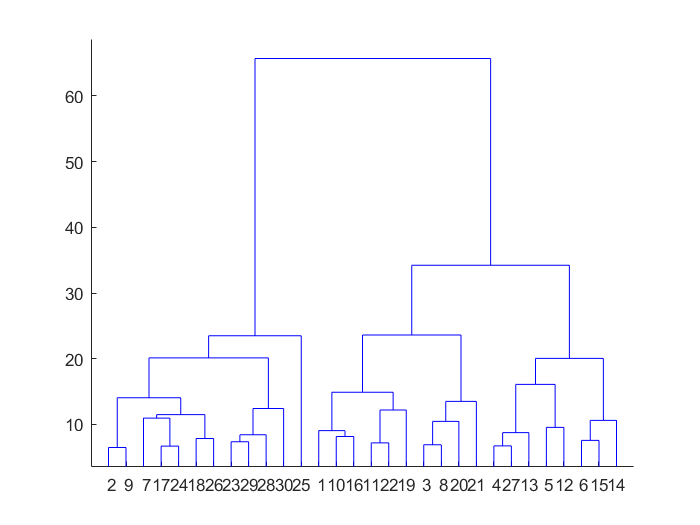

dendrogram(Z)


% Make and interpret clusters from the dendrogram
gc2 = cluster(Z,"maxclust",2)

gc2 =      2
     1
     2
     2
     2
     2
     1
     2
     1
     2


gc3 = cluster(Z,"maxclust",2)

gc3 =      2
     1
     2
     2
     2
     2
     1
     2
     1
     2


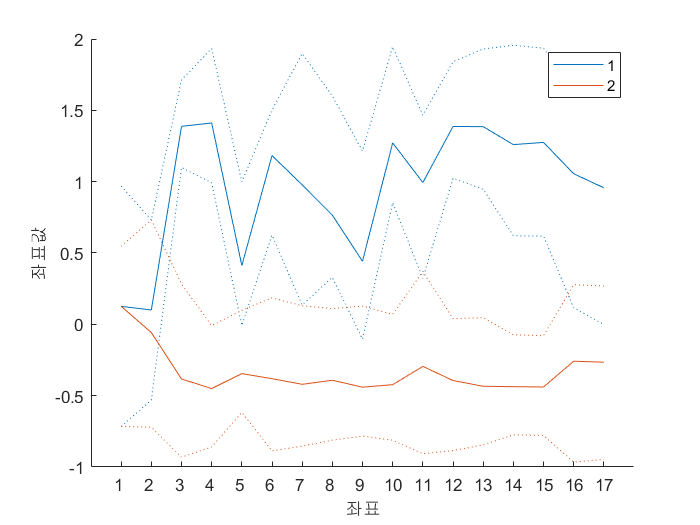


figure
parallelcoords(guardstats,"Group",gc2,"Quantile",0.25)

parallelcoords(guardstats,"Group",gc3,"Quantile",0,25)

다음 사용 중 오류가 발생함: internal.stats.parseArgs (42번 라인)
인수의 개수가 올바르지 않습니다.

오류 발생: parallelcoords (94번 라인)
                             internal.stats.parseArgs(pnames, dflts, varargin{:});


% 'evalclusters' function with 'linkage' option
% also find you the optimal number of clusters
clustEv1 = evalclusters(guardstats,"linkage","silhouette","KList",2:5)
clustEv2 = evalclusters(guardstats,"linkage","CalinskiHarabasz","KList",2:5)
clustEv3 = evalclusters(guardstats,"linkage","DaviesBouldin","KList",2:5)
clustEv4 = evalclusters(guardstats,"linkage","gap","KList",2:5)